# 4-bar linkage analysis** - **`kinematic analysis singularities`

Let's explore some of the kinematic singularities of the 4bar linkage shown in Figure_01 below.  Specifically we're interested in the configurations where:

- $L_1 =L_3$  and $L_2 =L_4$

- $L_3 =L_4$  and $L_1 =L_2$

**Figure 01:  the 4bar linkage**

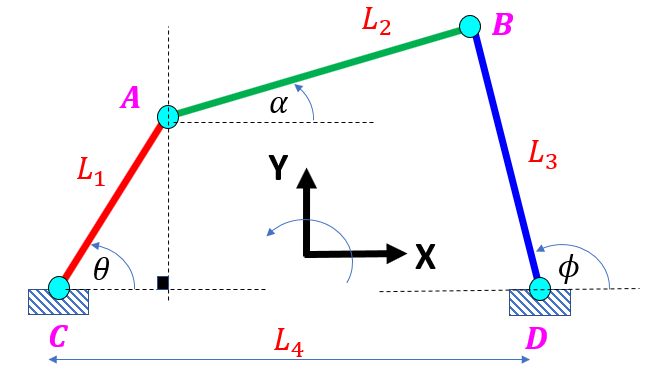

## Define the symbolic geometry parameters:

Recall the kinematic derivation that we saw previously:

syms L_1   L_2  L_3  L_4  theta phi

Let's define the relationships describing horizontal distances:

- 
$$L_4 \;\;=\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)\;+\;\;L_2 \ldotp \mathrm{cos}\left(\alpha \right)\;+\;\;L_3 \ldotp \mathrm{cos}\left(\pi -\phi \right)$$


- 
$$L_4 \;\;=\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)\;+\;\;L_2 \ldotp \mathrm{cos}\left(\alpha \right)-\;\;L_3 \ldotp \mathrm{cos}\left(\phi \right)$$


So we see that:

- $\;L_2 \ldotp \mathrm{cos}\left(\alpha \right)\;\;=L_4 \;-\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)\;+\;\;\;L_3 \ldotp \mathrm{cos}\left(\phi \right)$  ` .....    EQ_1`

And similarly the vertical distance:

- 
$$L_1 \ldotp \mathrm{sin}\left(\theta \right)\;\;+\;\;L_2 \ldotp \mathrm{sin}\left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \mathrm{sin}\left(\pi -\phi \right)$$


- 
$$L_1 \ldotp \mathrm{sin}\left(\theta \right)\;\;+\;\;L_2 \ldotp \mathrm{sin}\left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \mathrm{sin}\left(\phi \right)$$


So we see that:

- $L_2 \ldotp \mathrm{sin}\left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \mathrm{sin}\left(\phi \right)\;\;-\;\;L_1 \ldotp \mathrm{sin}\left(\theta \right)\;$`.....    EQ_2`

So let's square `EQ_1` and `EQ_2` and add them together

EQ_C = L_2^2 == (L_4 - L_1*cos(theta) + L_3*cos(phi))^2  +  (L_3*sin(phi) - L_1*sin(theta))^2

$$EQ\_C = {L_{2}}^{2}={\left(L_{4}+L_{3}\,\cos\left(\varphi \right)-L_{1}\,\cos\left(\theta \right)\right)}^{2}+{\left(L_{3}\,\sin\left(\varphi \right)-L_{1}\,\sin\left(\theta \right)\right)}^{2}$$

## Looking for $\phi =f\left(\theta \right)$

`EQ_C` is pretty ugly .... but we can use it to find a functional relationship between $\phi$and $\theta$, ie:  $\phi =f\left(\theta \right)$.  A trick that engineers have found (eg: REF_02, 03), is the following. Let:

- 
$$z=\mathrm{tan}\left(\frac{\phi }{2}\right)\;\Longrightarrow \;\;\;\;\mathrm{sin}\left(\phi \right)=\frac{2z}{1+z^2 }\;\;\;\;\;\;\mathrm{and}\;\;\;\;\;\;\;\mathrm{cos}\left(\phi \right)=\frac{1-z^2 }{1+z^2 }\;\;\;\;\;\;$$


This transformation allows us to convert **EQ_C** into a quadratic.  So let's substitute this into `EQ_C` and see what pops out:

syms z
sp   = (2*z)/(1 + z^2);
cp   = (1 - z^2)/(1 + z^2);
EQ_C = subs(EQ_C, {sin(phi), cos(phi)}, {sp, cp})

$$EQ\_C = {L_{2}}^{2}={\left(L_{1}\,\sin\left(\theta \right)-\frac{2\,L_{3}\,z}{z^{2}+1}\right)}^{2}+{\left(L_{1}\,\cos\left(\theta \right)-L_{4}+\frac{L_{3}\,\left(z^{2}-1\right)}{z^{2}+1}\right)}^{2}$$

`EQ_C` is just a quadratic in terms of $z$, which we can solve for:

the_z = solve(EQ_C, z);
the_z = simplify(the_z)

$$the\_z = \begin{array}{l} \left(\begin{array}{c} \frac{\sigma_{1}+2\,L_{1}\,L_{3}\,\sin\left(\theta \right)}{\sigma_{2}}\\ -\frac{\sigma_{1}-2\,L_{1}\,L_{3}\,\sin\left(\theta \right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(-{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{4}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}\right)\,\left({L_{1}}^{2}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}\right)}\\ \sigma_{2}={L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+{L_{3}}^{2}-2\,L_{3}\,L_{4}+{L_{4}}^{2} \end{array}$$

## Explore potential singularities for z1

OK: Let's look at the Numerator and Denominator of the **first** root:

[the_N, the_D] = numden(  the_z(1)  );
the_N          = simplify(the_N)

$$the\_N = \sqrt{\left(-{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{4}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}\right)\,\left({L_{1}}^{2}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}\right)}+2\,L_{1}\,L_{3}\,\sin\left(\theta \right)$$

the_D = simplify(the_D)

$$the\_D = {L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+{L_{3}}^{2}-2\,L_{3}\,L_{4}+{L_{4}}^{2}$$

### Case_01 :   

- $L_3 =L_4$  and $L_1 =L_2$

The Numerator:

simplify(  subs(the_N, [L_3, L_1], [L_4, L_2]), 10  )

$$ans = 2\,\sqrt{{L_{2}}^{2}\,{L_{4}}^{2}-{L_{2}}^{2}\,{L_{4}}^{2}\,{\cos\left(\theta \right)}^{2}}+2\,L_{2}\,L_{4}\,\sin\left(\theta \right)$$

So:

- when $-\pi \le \;\theta \le 0$   then  the Numerator is always zero

- when $0<\;\theta <\pi$   then  the Numerator is NEVER zero

The Denominator:

simplify(  subs(the_D, [L_3, L_1], [L_4, L_2])  )

$$ans = 0$$

So 

- the Denominator is ALWAYS zero

### Case_02 :

-  $L_1 =L_3$  and $L_2 =L_4$

The Numerator:

simplify(  subs(the_N, [L_1, L_2], [L_3, L_4]), 10  )

$$ans = 2\,\sqrt{{L_{3}}^{2}\,{L_{4}}^{2}-{L_{3}}^{2}\,{L_{4}}^{2}\,{\cos\left(\theta \right)}^{2}}+2\,{L_{3}}^{2}\,\sin\left(\theta \right)$$

So:

- The Numeraror is zero when $\theta =m\ldotp \pi$$\mathrm{for}\;m=\mp 1,\mp 2,\mathrm{etc}$

- and IFFF $L_4 =L_3$, then when $-\pi \le \;\theta \le 0$  the Numerator is zero

The Denominator:

simplify(  subs(the_D, [L_1, L_2], [L_3, L_4])  )

$$ans = 2\,L_{3}\,\left(\cos\left(\theta \right)+1\right)\,\left(L_{3}-L_{4}\right)$$

So,

- the Denominator is zero when $\theta =m\ldotp \pi \;\;\mathrm{for}\;m=\mp 1,\mp 3,\mathrm{etc}$ 

- the Denominator is zero if $L_3 =L_4$

Let's look at a specifc NUMERIC example for **CASE_02**:

- $L_1 =L_3 =0\ldotp 4$  and $L_2 =L_4 =2$

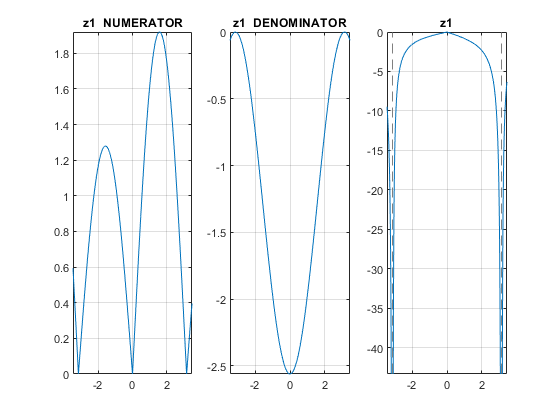

spec_N = subs(the_N,    [L_1, L_2, L_3, L_4], [0.4,2,0.4,2]);
spec_D = subs(the_D,    [L_1, L_2, L_3, L_4], [0.4,2,0.4,2]);
spec_z = subs(the_z(1), [L_1, L_2, L_3, L_4], [0.4,2,0.4,2]);

tmp_theta_range = [-1.1*pi 1.1*pi]; %[0.999 1.01]*pi;

figure;
    subplot(1,3,1); fplot(spec_N, tmp_theta_range); grid('on'); title('z1  NUMERATOR')
    subplot(1,3,2); fplot(spec_D, tmp_theta_range); grid('on'); title('z1  DENOMINATOR')
    subplot(1,3,3); fplot(spec_z, tmp_theta_range); grid('on'); title('z1')

## Explore potential singularities for z2

OK: Let's look at the Numerator and Denominator of the **second** root:

[the_N, the_D] = numden(  the_z(2)  );
the_N          = simplify(the_N)

$$the\_N = 2\,L_{1}\,L_{3}\,\sin\left(\theta \right)-\sqrt{\left(-{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{4}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}\right)\,\left({L_{1}}^{2}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}\right)}$$

the_D = simplify(the_D)

$$the\_D = {L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+{L_{3}}^{2}-2\,L_{3}\,L_{4}+{L_{4}}^{2}$$

### Case_01 :   

- $L_3 =L_4$  and $L_1 =L_2$

The Numerator:

simplify(  subs(the_N, [L_3, L_1], [L_4, L_2]),10  )

$$ans = 2\,L_{2}\,L_{4}\,\sin\left(\theta \right)-2\,\sqrt{{L_{2}}^{2}\,{L_{4}}^{2}\,{\sin\left(\theta \right)}^{2}}$$

So:

- when $0\le \theta \le \pi$   then  the Numerator is always zero

- when $-\pi <\;\theta <0$   then  the Numerator is NEVER zero

The Denominator:

simplify(  subs(the_D, [L_3, L_1], [L_4, L_2])  )

$$ans = 0$$

So the Denominator is always zero.

### Case_02 :

-  $L_1 =L_3$  and $L_2 =L_4$

The Numerator:

simplify(  subs(the_N, [L_1, L_2], [L_3, L_4])  )

$$ans = 2\,{L_{3}}^{2}\,\sin\left(\theta \right)-2\,\sqrt{{L_{3}}^{2}\,{L_{4}}^{2}\,{\sin\left(\theta \right)}^{2}}$$

So:

- The Numeraror is zero when $\theta =m\ldotp \pi$$\mathrm{for}\;m=\mp 1,\mp 2,\mathrm{etc}$

- and IFFF $L_4 =L_3$, then when $0\le \theta \le \pi$  the Numerator is always zero

The Denominator:

simplify(  subs(the_D, [L_1, L_2], [L_3, L_4])  )

$$ans = 2\,L_{3}\,\left(\cos\left(\theta \right)+1\right)\,\left(L_{3}-L_{4}\right)$$

So:

- The Denominator is zero when $\theta =m\ldotp \pi \;\;\mathrm{for}\;m=\mp 1,\mp 3,\mathrm{etc}$ 

- And the Denominator is ALWAYS zero if $L_3 =L_4$

Let's look at a specifc NUMERIC example for **CASE_02**:

- $L_1 =L_3 =0\ldotp 4$  and $L_2 =L_4 =2$

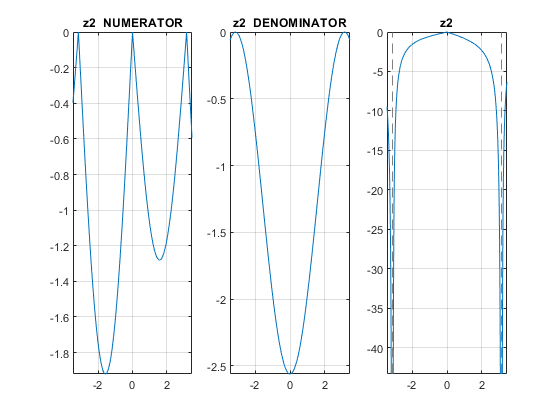

spec_N = subs(the_N,    [L_1, L_2, L_3, L_4], [0.4,2,0.4,2]);
spec_D = subs(the_D,    [L_1, L_2, L_3, L_4], [0.4,2,0.4,2]);
spec_z = subs(the_z(1), [L_1, L_2, L_3, L_4], [0.4,2,0.4,2]);
tmp_theta_range = [-1.1*pi 1.1*pi]; %[0.999 1.01]*pi;
figure;
subplot(1,3,1); fplot(spec_N, tmp_theta_range); grid('on'); title('z2  NUMERATOR')
subplot(1,3,2); fplot(spec_D, tmp_theta_range); grid('on'); title('z2  DENOMINATOR')
subplot(1,3,3); fplot(spec_z, tmp_theta_range); grid('on'); title('z2')

## Create MATLAB functions - part 1

Let's convert the expression for $z\;$into a MATLAB function, ie:

- 
$$z\left(L_1 ,L_2 ,L_3 ,L_4 ,\;\theta \right)$$


Let's store this functional relationship into the following MATLAB *.m function files:

- `bh_z_func.m`

LOC_create_MATLAB_functions(the_z)

## Create MATLAB functions - part 2

So what do these functions look like ? 

THE_FILE_TO_LOOK_AT = "bh_z_func.m";
%dbtype(THE_FILE_TO_LOOK_AT)

## Explore "fringe" cases where the numeric implementation is different to the SYMBOLIC

Recall our `the_z`:

the_z

$$the\_z = \begin{array}{l} \left(\begin{array}{c} \frac{\sigma_{1}+2\,L_{1}\,L_{3}\,\sin\left(\theta \right)}{\sigma_{2}}\\ -\frac{\sigma_{1}-2\,L_{1}\,L_{3}\,\sin\left(\theta \right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(-{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{4}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}\right)\,\left({L_{1}}^{2}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}\right)}\\ \sigma_{2}={L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+{L_{3}}^{2}-2\,L_{3}\,L_{4}+{L_{4}}^{2} \end{array}$$

Consider the case when:

- $L_1 =L_3$   and   $L_2 =L_4$   and   $\theta =0$

If we substitute into the original SYMBOLIC versions of $z_1 \;\mathrm{and}\;z_2$ what do we get ?

subs(the_z, [  L_1,   L_2,   L_3,   L_4, theta], ...
            [  L_1,   L_2,   L_1,   L_2, 0])

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

If we substitute SYMBOLIC variables into our  "auto created" MATLAB functions what happens ?

[some_z,~,~] = bh_z_func(L_1, L_2, L_1, L_2, 0)

$$some\_z = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

OK: what about if we substitute NUMERIC values - again for the case where

- $L_1 =L_3$   and   $L_2 =L_4$   and   $\theta =0$

my_L1 = 0.4;
my_L2 = 2;
my_L3 = my_L1;
my_L4 = my_L2;

Substitute NUMERIC values into the original SYMBOLIC expressions:

some_z = subs(the_z, [    L_1,   L_2,   L_3,   L_4, theta], ...
                     [  my_L1, my_L2, my_L3, my_L4, 0])

$$some\_z = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

What about if we substitute these same numeric values into the "auto created" MATLAB functions:

[some_z,some_num,some_den] = bh_z_func(my_L1, my_L2, my_L3, my_L4, 0)

some_z = 	1.0e+-7 *

   0.0000 - 0.1473i
   0.0000 + 0.1473i


some_num = 	1.0e+-7 *

   0.0000 + 0.3770i
   0.0000 - 0.3770i


some_den =    -2.5600
   -2.5600


What we're seeing above is the result of machine precision used in the floating point arithmatic.  Recall that the expressions for the roots for $z_1 \;\mathrm{and}\;z_2$ involve a square root, and what we've stumbled upon here is a case where instead of finding the root of ZERO .... our floating point arithmatic caused a square root of a small NEGATIVE number .... which in turn resulted in a small complex number.  We can "look" for and correct these fringe cases:

[some_z, ~, ~] = bh_z_calc_util(my_L1, my_L2, my_L3, my_L4, 0, "CALC_Z")

some_z =      0
     0


And of course test that our correction is robust across the angular range:

tt_list = linspace(-pi*0.99, pi*0.99, 10);
for tt=tt_list
    tmp_z_symb =  subs(the_z, [    L_1,   L_2,   L_3,   L_4, theta], ...
                              [  my_L1, my_L2, my_L3, my_L4, tt]);
    tmp_z_mlf =   bh_z_calc_util(my_L1, my_L2, my_L3, my_L4, tt, "CALC_Z");
    
    [double(tmp_z_symb).' ; tmp_z_mlf.']
end

ans =   -63.6567   95.4851
  -63.6567   95.4851


ans =    -2.6464    3.9696
   -2.6464    3.9696


ans =    -1.1708    1.7563
   -1.1708    1.7563


ans =    -0.5704    0.8556
   -0.5704    0.8556


ans =    -0.1745    0.2618
   -0.1745    0.2618


ans =    -0.2618    0.1745
   -0.2618    0.1745


ans =    -0.8556    0.5704
   -0.8556    0.5704


ans =    -1.7563    1.1708
   -1.7563    1.1708


ans =    -3.9696    2.6464
   -3.9696    2.6464


ans =   -95.4851   63.6567
  -95.4851   63.6567


# Helper Functions

Let's produce MATLAB functions from our symbolic expressions:

function LOC_create_MATLAB_functions(the_z)
    
    syms L_1   L_2  L_3  L_4  theta phi
        
    [N1,D1] = numden( the_z(1) );
    [N2,D2] = numden( the_z(2) );
    
    the_num = [N1;N2];
    the_den = [D1;D2];
    
    f_z = matlabFunction( the_z, the_num, the_den, ...
                                 'File', 'bh_z_func', 'Vars', [L_1, L_2, L_3, L_4, theta]);    
    
end